Question 4

a)

s=tf('s')

s =
 
  s
 
Continuous-time transfer function.



G=tf(50/((s+10)*(s+8)));
figure;
bode(G)

b)

F=tf(20,[1 2 20])

F =
 
        20
  --------------
  s^2 + 2 s + 20
 
Continuous-time transfer function.



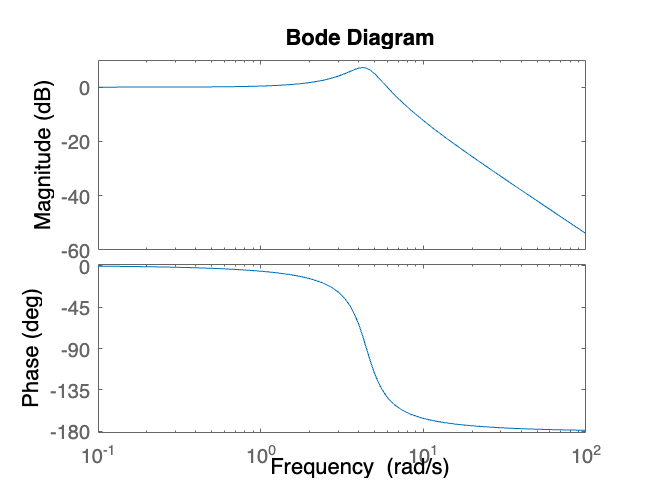

figure;
bode(F)

Question 5

s=tf('s')

s =
 
  s
 
Continuous-time transfer function.



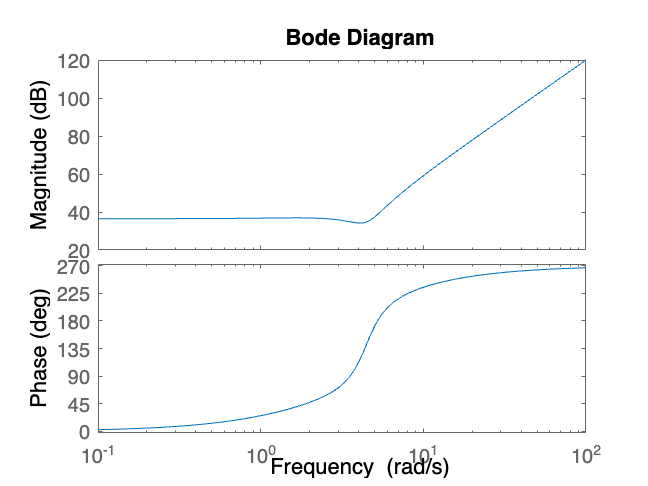

A=tf(((s+2)*(s+5))/(s+3)*(s^2+2*s+20));
bode(A)


%b
W=tf(450,[1 3 10 30 150])

W =
 
                 450
  ---------------------------------
  s^4 + 3 s^3 + 10 s^2 + 30 s + 150
 
Continuous-time transfer function.



bode(W)


Question 6

clear;
clc;
close all;
syms s;
sys1 = 10;
sys2 = 10;
sys3 = 1/(s+12);
sys4 = 20/s;
sys5 = 0.2*s;
sys_OA_1 = sys1+sys2;
sys_OA_2 = sys3*sys4;
sys_OA_3 = sys_OA_2/(1+sys_OA_2*sys5);
sys_OA_4 = sys_OA_3*sys_OA_1;
sys_OA_5 = sys_OA_4/(1+sys_OA_4);
simplify(sys_OA_5)

$$ans = \frac{400}{s^{2}+16\,s+400}$$

Question 7

num=1;
den=[1 14 48 01]

den =      1    14    48     1


H=tf(num,den)

H =
 
             1
  -----------------------
  s^3 + 14 s^2 + 48 s + 1
 
Continuous-time transfer function.



figure;
rlocus(H)
sgrid
figure;
step(H)
%conclude it is unstable for K>637

Question 8

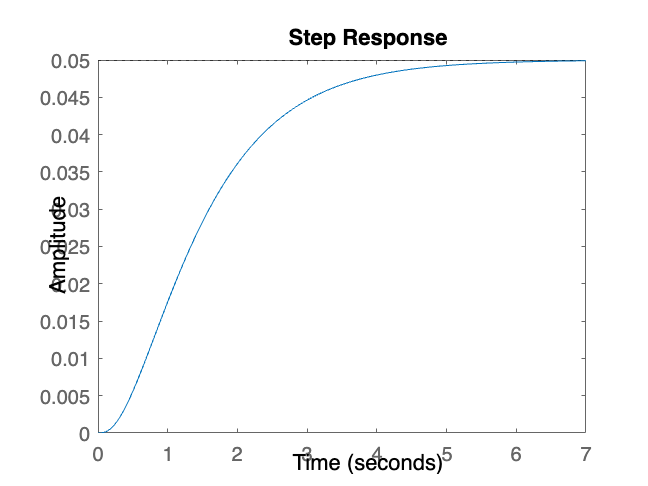

clear;
clc;
close all;
s=tf('s'); 
G=1/((s+1)*(s+2)*(s+10)); 
step(G)

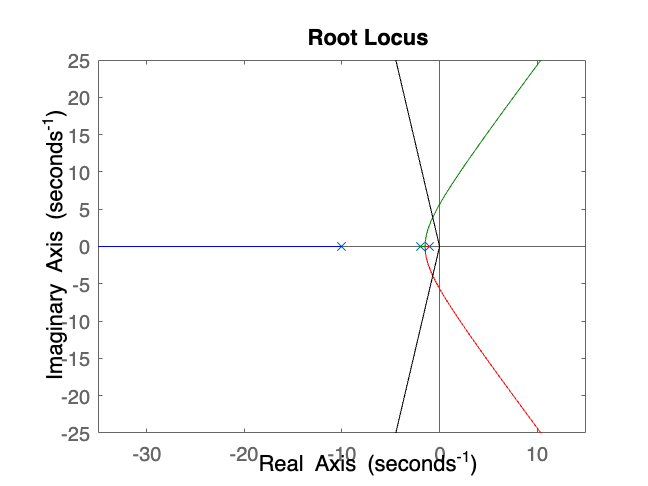

figure;
rlocus(G)
hold on;
zeta=0.174;
theta_required=atan(sort(1-zeta^2)/zeta);
plot([-25 0],[-tan(theta_required)*-25 0],'k-')
plot([-25 0],[tan(theta_required)*-25 0],'k-')

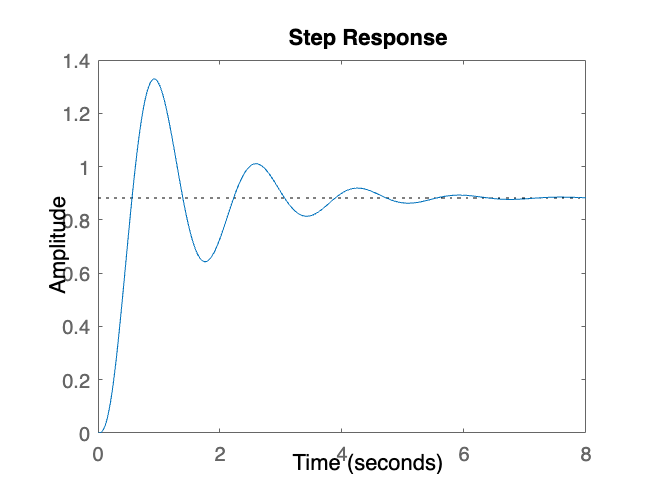

K=150;%random gain value matlab was not letting me access figure
controller=tf(K,1);
T=series(controller,G);
T=feedback(T,1);
figure;
step(T)

c


Geq=1/((s+1)*(s+2)*(s+10))

Geq =
 
             1
  ------------------------
  s^3 + 13 s^2 + 32 s + 20
 
Continuous-time transfer function.



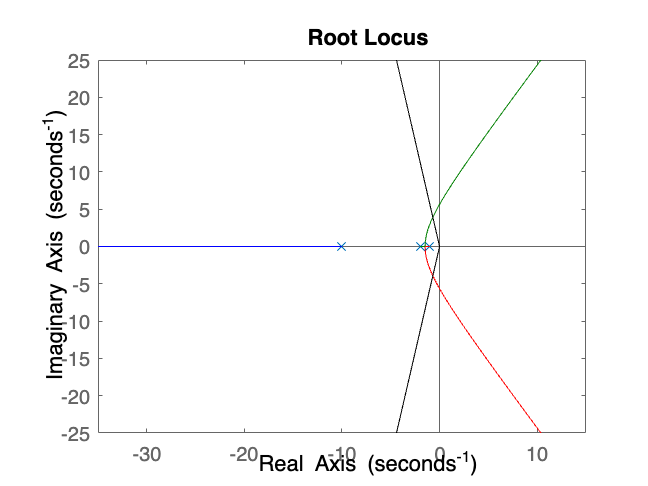


figure;
rlocus(Geq)
hold on;
zeta=0.174;
theta_required=atan(sqrt(1-zeta^2)/zeta);
plot([-25 0], [-tan(theta_required)*-25 0],'k-')
plot([-25 0], [tan(theta_required)*-25 0],'k-')

K=160%random gain value matlab was not letting me open the figure

K = 160

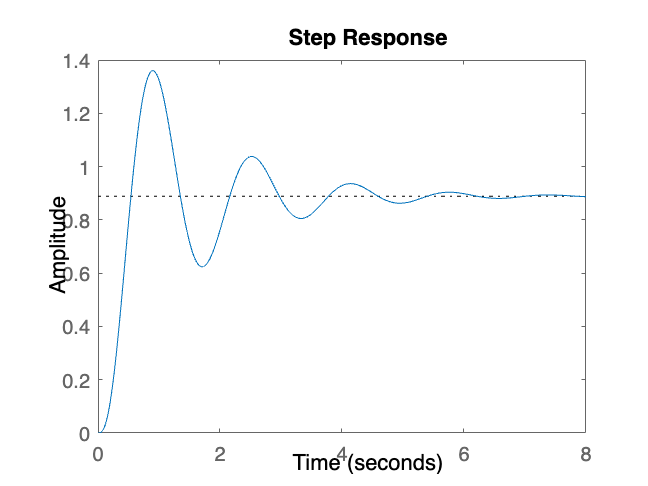

controller=tf(K,1);
T=series(controller,Geq);
T=feedback(T,1);
figure;
step(T)